Xialei Fang

200434895

% Load the video
videoFile = 'Large Speed Bump\C2.mp4';
vid = VideoReader(videoFile);

a)	Based on the number of pixels the vehicle covers how many cm is each pixel. 

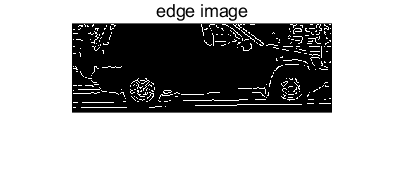

% Choose a frame that the whole car is in the screen
frame = read(vid, round(vid.FrameRate * 6.8));

% Crop the background part of the frame to better extract information from
% the car
croppedFrame = frame(260:400, 440:850, :); 

grayFrame = rgb2gray(croppedFrame);
enhancedFrame = imadjust(grayFrame); 

% Edge Detection
edges = edge(enhancedFrame, 'canny');
imshow(edges);
title('edge image');

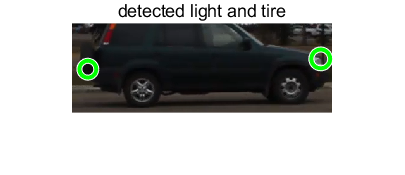

Pixel-to-cm ratio: 1.25 cm/pixel


% Circle detection for car lights
% As back light is hard to detect, so we detect front light and tire
[centers, radii, metric] = imfindcircles(edges, [10 30], 'Sensitivity', 0.9);

% Identify Front Light and tire on the back
if ~isempty(centers)
    % Assume the leftmost and rightmost detected circles are the light and
    % tire
    [~, tireIdx] = min(centers(:, 1));  % tire (leftmost)
    [~, lightIdx] = max(centers(:, 1));   % light (rightmost)

    % Display detected light and tire
    figure; imshow(croppedFrame); 
    title('detected light and tire'); hold on;
    viscircles(centers(tireIdx, :), radii(tireIdx), 'Color', 'g', 'LineWidth', 2);
    viscircles(centers(lightIdx, :), radii(lightIdx), 'Color', 'g', 'LineWidth', 2);

    pixelDistance = abs(centers(lightIdx, 1) - centers(tireIdx, 1));
    % Convert the car length to cm
    % As the center point of the circle is used to calculate the car
    % length, assume the center point of the tire cicle is half of the tire
    % width
    realLengthCM = (177.6 + 8.1/2) * 2.54;
    pixelToCM = realLengthCM / pixelDistance;

    fprintf('Pixel-to-cm ratio: %.2f cm/pixel\n', pixelToCM);
else
    fprintf('Error: No car lights detected.\n');
end

b)	What is the speed of the vehicle average and instantaneous? Provide a graph of the instantaneous velocity in time. 

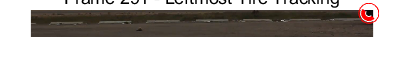

% Track the car and calculate the instantenous speed and average speed
frameRate = vid.FrameRate;
sampleRate = 3;              
frameInterval = round(frameRate / sampleRate);

tirePositions = [];
timeStamps = [];
prevTireCenter = [];
stabilizationWindow = 5;
tireRadiusRange = [15 40];

for frameIdx = 1:frameInterval:vid.NumFrames
    frame1 = read(vid, frameIdx);
    
    % crop the frame for better detection
    croppedFrame1 = frame1(320:420, :, :);
    
    % Enhanced processing for tires
    grayFrame1 = rgb2gray(croppedFrame1);
    enhancedFrame1 = imadjust(grayFrame1, [0.2 0.8], []);
    
    % Edge detection
    edges1 = edge(enhancedFrame1, 'Canny', [0.01 0.15]);
    closedEdges = imclose(edges1, strel('disk', 2));
    
    % Detect circles (tires)
    [centers1, radii1, metric1] = imfindcircles(closedEdges, tireRadiusRange, ...
        'ObjectPolarity', 'dark', 'Sensitivity', 0.9);
    
    % Select and validate tire
    if ~isempty(centers1)
        % Leftmost circle is rear tire
        [~, leftmostIdx] = min(centers1(:,1));
        candidateCenter = centers1(leftmostIdx,:);
        candidateRadius = radii1(leftmostIdx);
        
        % If we have previous position, use nearest in expected area
        if ~isempty(prevTireCenter)
            distances = sqrt(sum((centers1 - prevTireCenter).^2, 2));
            [~, nearestIdx] = min(distances);
            if distances(nearestIdx) < 50 
                candidateCenter = centers1(nearestIdx,:);
                candidateRadius = radii1(nearestIdx);
            end
        end
        
        % Validate circularity
        mask = false(size(closedEdges));
        mask(round(candidateCenter(2)), round(candidateCenter(1))) = true;
        mask = bwdist(mask) <= candidateRadius;
        circularity = sum(mask(:) & closedEdges(:)) / (2*pi*candidateRadius);
        
        if circularity > 0.65
            prevTireCenter = candidateCenter;
            tirePositions = [tirePositions; candidateCenter];
            timeStamps = [timeStamps; frameIdx/frameRate];
            
        end
    end
    
    % Visualization
    figure(1); clf;
    imshow(croppedFrame1); hold on;
    if ~isempty(centers1)
        viscircles(centers1, radii1, 'EdgeColor', 'b', 'LineWidth', 1);
        if exist('candidateCenter', 'var')
            viscircles(candidateCenter, candidateRadius, 'EdgeColor', 'r', 'LineWidth', 2);
            plot(candidateCenter(1), candidateCenter(2), 'ro', 'MarkerSize', 10);
        end
    end
    title(sprintf('Frame %d - Leftmost Tire Tracking', frameIdx));
    drawnow;
end

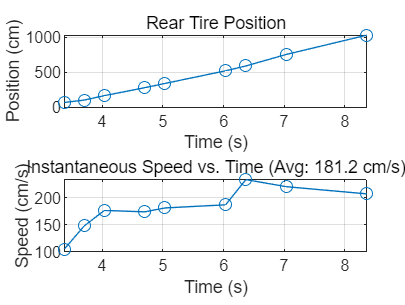


% Calculate Speed with Validation
if length(tirePositions) > 3
    % Smooth positions
    xPositions = movmedian(tirePositions(:,1), 3);
    
    xPositionsCM = xPositions * pixelToCM;
    % Use gradient to calculate instantaneous speed (cm/s)
    dx = gradient(xPositionsCM);
    dt = gradient(timeStamps);
    instSpeed = dx ./ dt;

    % Plot results
    figure;
    subplot(2,1,1);
    plot(timeStamps, xPositionsCM, '-o');
    xlabel('Time (s)'); 
    ylabel('Position (cm)');
    title('Rear Tire Position');
    grid on;
    
    subplot(2,1,2);
    plot(timeStamps, instSpeed, '-o');
    xlabel('Time (s)'); 
    ylabel('Speed (cm/s)');
    title(sprintf('Instantaneous Speed vs. Time (Avg: %.1f cm/s)', mean(instSpeed)));
    grid on;
else
    error('Insufficient tire detections - adjust parameters or check video');
end

c)	Find the wheels of the CR-V as it goes over the speed bump and present representative images 

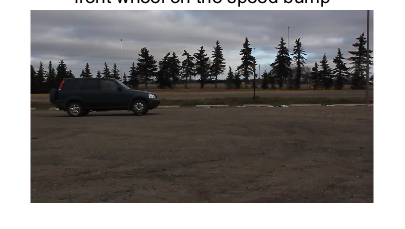

% Find the wheels of the CR-V as it goes over the speed bump
figure;
front = read(vid, round(vid.FrameRate * 4.25));
imshow(front);
title("front wheel on the speed bump");

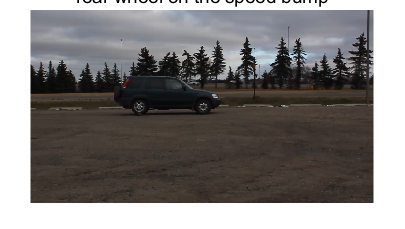


rear = read(vid, round(vid.FrameRate * 5.95));
imshow(rear);
title("rear wheel on the speed bump");

flat = read(vid, round(vid.FrameRate * 6.2));

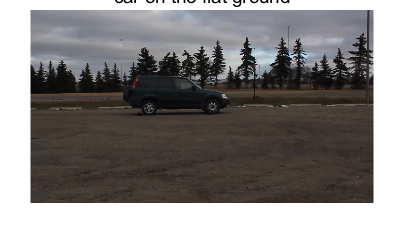

imshow(flat);
title("car on the flat ground");

d)	How much do the vehicle’s wheel move in the vertical direction as it goes over the speed bump? 

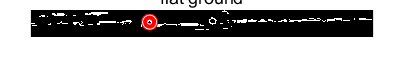

% Detect wheel positions
figure;
flatWheel = detectWheel(flat);
title("flat ground");

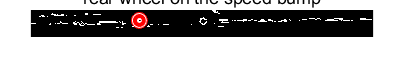


figure;
rearWheel = detectWheel(rear);
title("rear wheel on the speed bump");


% Calculate the vertical displacement of the rear wheel
rearWheelDisplacement_px = abs(flatWheel(2) - rearWheel(2));
% Convert pixels to cm
rearWheelDisplacement_cm = rearWheelDisplacement_px * pixelToCM;

fprintf('Rear wheel displacement: %.2f cm\n', rearWheelDisplacement_cm);

Rear wheel displacement: 7.67 cm


e)	How much do the vehicle’s body move in the vertical direction as it goes over the speed bump? 

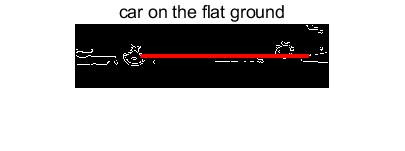

% Detect body reference points
figure;
flatBodyY = detectCarBody(flat); 
title("car on the flat ground");

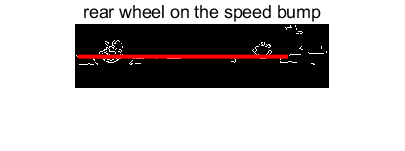


figure;
bumpBodyY = detectCarBody(rear); 
title("rear wheel on the speed bump");


% Calculate vertical displacements
bodyDisplacement_px = abs(flatBodyY - bumpBodyY);

% Convert pixels to cm
bodyDisplacement_cm = bodyDisplacement_px * pixelToCM;
fprintf('Body displacement: %.2f cm\n', bodyDisplacement_cm);

Body displacement: 1.25 cm


f)	What is the height of the speed bump? 

% Estimate bump height
speedBumpHeight = rearWheelDisplacement_cm - bodyDisplacement_cm;

fprintf('Estimated speed bump height: %.2f cm\n', speedBumpHeight);

Estimated speed bump height: 6.41 cm


function wheelCenter = detectWheel(frame)
    % Convert to grayscale and enhance
    crop = frame(320:420, :, :);
    grayFrame = rgb2gray(crop);
    enhancedFrame = imadjust(grayFrame, [0.2 0.8], []);

    % Edge detection and noise reduction
    edges = edge(enhancedFrame, 'Canny', [0.01 0.15]);
    closedEdges = imclose(edges, strel('disk', 2));

    % Circle detection for tire
    [centers, radii, ~] = imfindcircles(closedEdges, [15 40], ...
                                        'ObjectPolarity', 'dark', ...
                                        'Sensitivity', 0.9);

    % Select the wheel closest to the bottom (likely a rear wheel)
    if ~isempty(centers)
        [~, bottomIdx] = min(centers(:,1));  
        wheelCenter = centers(bottomIdx, :);
        wheelRadii = radii(bottomIdx);
    else
        wheelCenter = [NaN NaN]; 
    end

    figure;
    imshow(closedEdges); hold on;
    if ~isempty(wheelCenter)
        viscircles(wheelCenter, wheelRadii, 'Color', 'r', 'LineWidth', 2);
        plot(wheelCenter(1), wheelCenter(2), 'ro', 'MarkerSize', 8);
    end
hold off;

end

function bodyYPosition = detectCarBody(frame)
    grayFrame = rgb2gray(frame);  
    croppedFrame = grayFrame(320:420, 350:750); 
    enhancedFrame = imadjust(croppedFrame, [0.2 0.9], []);
    
    edges = edge(enhancedFrame, 'Canny', [0.01 0.15]);

    % Hough Transform for Line Detection
    [H, theta, rho] = hough(edges);
    peaks = houghpeaks(H, 10, 'Threshold', ceil(0.3 * max(H(:))));
    lines = houghlines(edges, theta, rho, peaks, 'FillGap', 60, 'MinLength', 50);

    bodyYPosition = NaN;

    figure; imshow(edges); hold on;
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];

        % Check if the line is horizontal and within x-range
        angle = atan2d(xy(2,2) - xy(1,2), xy(2,1) - xy(1,1));
        if abs(angle) < 10  
            bodyYPosition = mean(xy(:,2));
            plot(xy(:,1), xy(:,2), 'r-', 'LineWidth', 2);
            break;
        end
    end

    hold off;
end

